
% store = {};
% store{1} = clustAssignments;
% store{2} = cycle3_assignment;
% store{3} = sub_divide_assign;
% store{4} = X;
%writecell(store,'mnistResults.txt');
% s = struct;
% s.cycle1 = clustAssignments;
% s.cycle2 = cycle3_assignment;
% s.cycle2 = cycle3_assignment;
% s.subdivi = sub_divide_assign;
% s.data = X;
% s.sub_label = subdivi_winner_idx;
% save('mnist_cycle2.mat','s')


% load('mnist_for_den.mat', 's');
% clustAssignments = s.cycle1;
% cycle3_assignment = s.cycle2;
% sub_divide_assign = s.subdivi;
% subdivi_winner_idx = s.sub_label;
% X = s.data;

clear
load("MNIST_LIHC_MERGE_DEN.mat")
SetRNG(111)

ans = struct with fields:
     Type: 'simdTwister'
     Seed: 111
    State: [776×1 uint32]


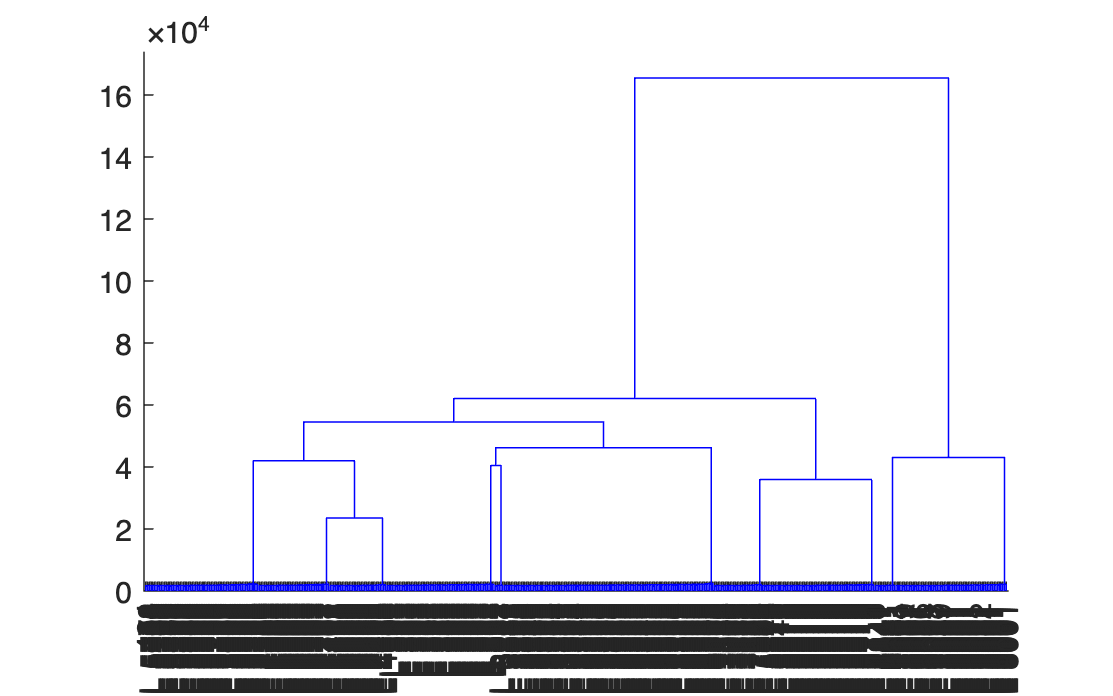


X_cell = {};
leaf_cell = [];
labels = [];
unique_cluster = unique(clustAssignments,'stable');
non_divi = setdiff(unique_cluster,subdivi_winner_idx);
unique_cluster = [subdivi_winner_idx;non_divi];

for c = 1:size(unique_cluster,1);
    this = unique_cluster(c);
    data_idx = find(clustAssignments == this);
    num = length(data_idx);
    X1 = X(:,data_idx)';
    Z = linkage(X1);
    max_leaf = max(max(Z(:,1:2))); 
    X_cell{c} = X1;
    leaf_cell = [leaf_cell;max_leaf];
    labels = [labels;this*ones(num,1)];
end


X_total = X_cell{1};
for i = 2:size(unique(clustAssignments),1);
    X_total = [X_total;X_cell{i} + sum(leaf_cell(1:i-1))];
end
str_labels = cellstr(num2str(labels,'L %d'));
Z_C1 = linkage(X_total);
%Z_C1(end-10:end,3) = Z_C1(end-10:end,3)*0.2;
h = dendrogram(Z_C1,500,'Labels',str_labels');

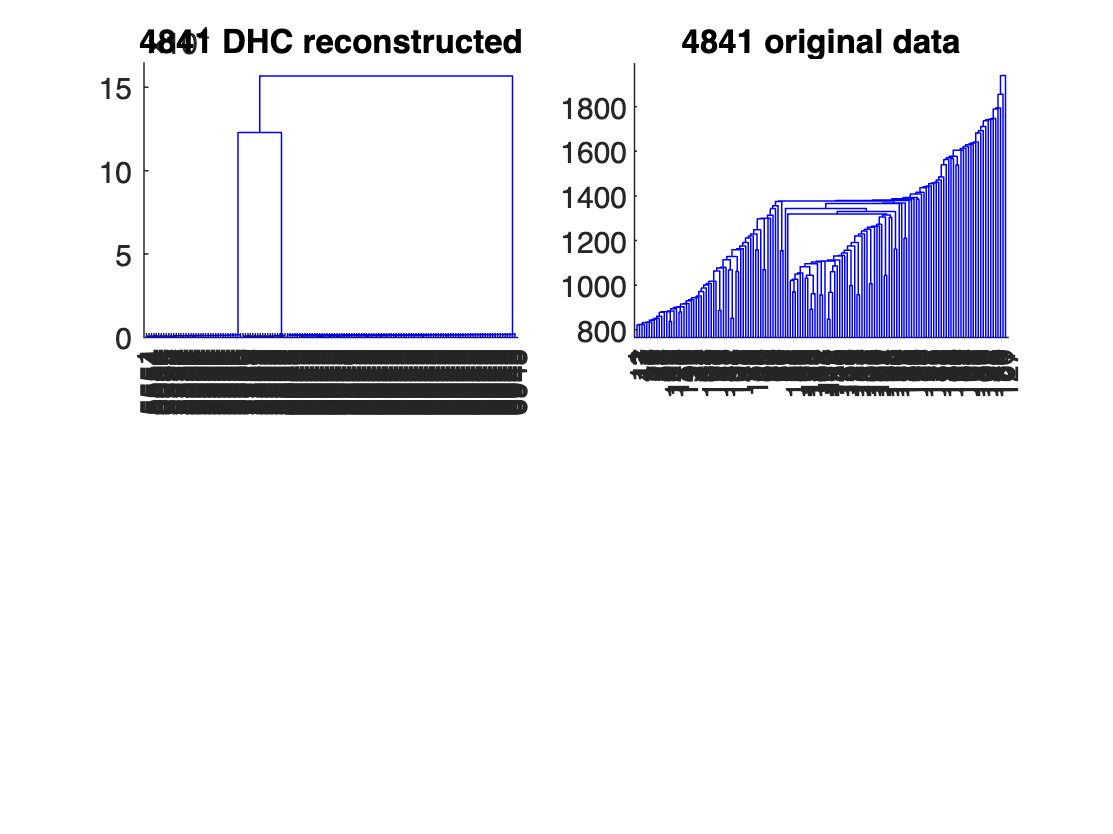

X_cell = {};
leaf_cell = [];
c2_labels = [];
c3_labels = [];
k = 0;
X_total = [];
m = 1;
cycle3_distribution = cycle3_assignment{m};
cycle3_distribution(find(cycle3_distribution(:,2)<20),:) = [];
for n = 1:length(cycle3_distribution(:,1));
    k = k+1;
    data_idx = find(sub_divide_assign == cycle3_distribution(n,1));
    X1 = X(:,data_idx)';
    X_total = [X_total;X1];
    Z = linkage(X1);
    max_leaf = max(max(Z(:,1:2)));
    X_cell{k} = X1;
    leaf_cell = [leaf_cell;max_leaf];
    num = length(data_idx);
    c2_label = subdivi_winner_idx(m);
    c3_label = cycle3_distribution(n,1);
    c2_labels = [c2_labels;c2_label*ones(num,1)];
    c3_labels = [c3_labels;c3_label*ones(num,1)];
end
X_sub = X_cell{1};
for i = 2:size(X_cell,2);
    X_sub = [X_sub;X_cell{i} + 10*sum(leaf_cell(1:i-1))];
end
Z = linkage(X_sub);
Z1 = linkage(X_total);
c3_labels = num2str(c3_labels);
figure;
subplot(2,2,1)
h = dendrogram(Z,150,'Labels',c3_labels);
title(string(subdivi_winner_idx(m))+' DHC reconstructed')
subplot(2,2,2)
h = dendrogram(Z1,150);
title(string(subdivi_winner_idx(m))+' original data')

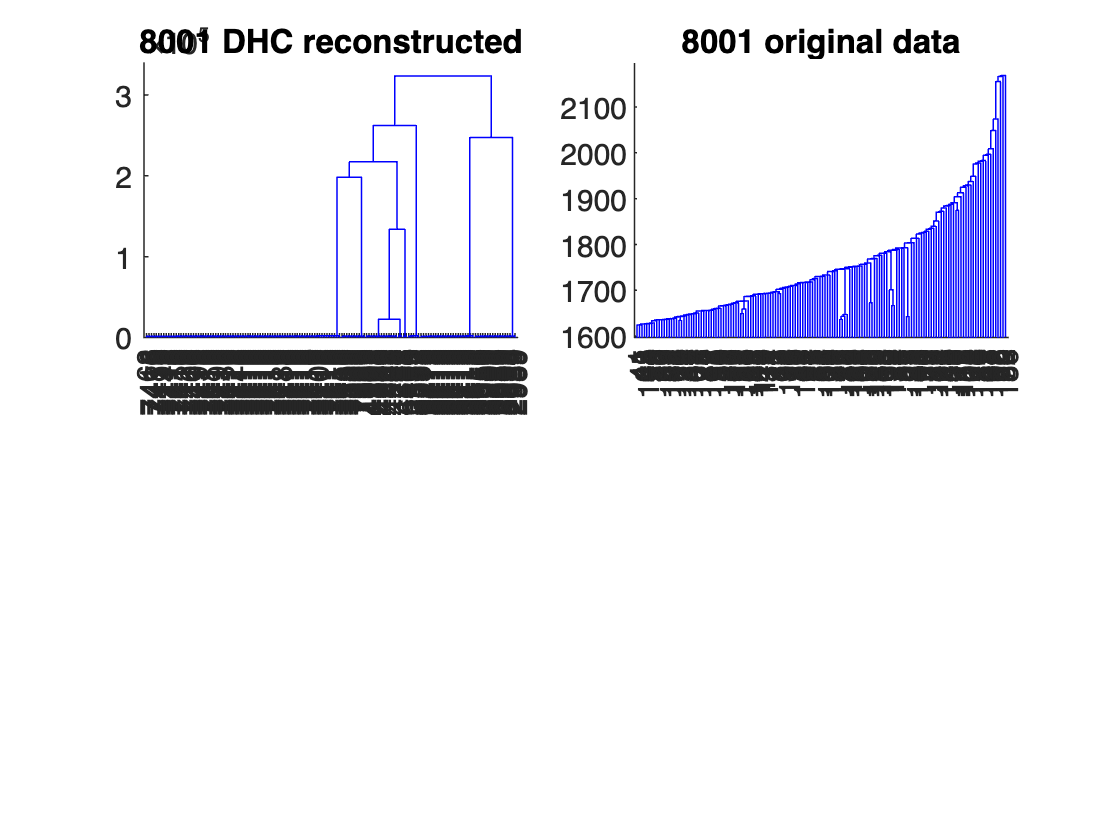



X_cell = {};
leaf_cell = [];
c2_labels = [];
c3_labels = [];
k = 0;
X_total = [];
m = 2;
cycle3_distribution = cycle3_assignment{m};
cycle3_distribution(find(cycle3_distribution(:,2)<20),:) = [];
for n = 1:length(cycle3_distribution(:,1));
    k = k+1;
    data_idx = find(sub_divide_assign == cycle3_distribution(n,1));
    X1 = X(:,data_idx)';
    Z = linkage(X1);
    max_leaf = max(max(Z(:,1:2)));
    X_cell{k} = X1;
    X_total = [X_total;X1];
    leaf_cell = [leaf_cell;max_leaf];
    num = length(data_idx);
    c2_label = subdivi_winner_idx(m);
    c3_label = cycle3_distribution(n,1);
    c2_labels = [c2_labels;c2_label*ones(num,1)];
    c3_labels = [c3_labels;c3_label*ones(num,1)];
end
X_sub2 = X_cell{1};
for i = 2:size(X_cell,2);
    X_sub2 = [X_sub2;X_cell{i} + 10*sum(leaf_cell(1:i-1))];
end
Z = linkage(X_sub2);
Z1 = linkage(X_total);
c3_labels = num2str(c3_labels);
figure;
subplot(2,2,1)
h = dendrogram(Z,150,'Labels',c3_labels);
title(string(subdivi_winner_idx(m))+' DHC reconstructed')
subplot(2,2,2)
h = dendrogram(Z1,150);
title(string(subdivi_winner_idx(m))+' original data')

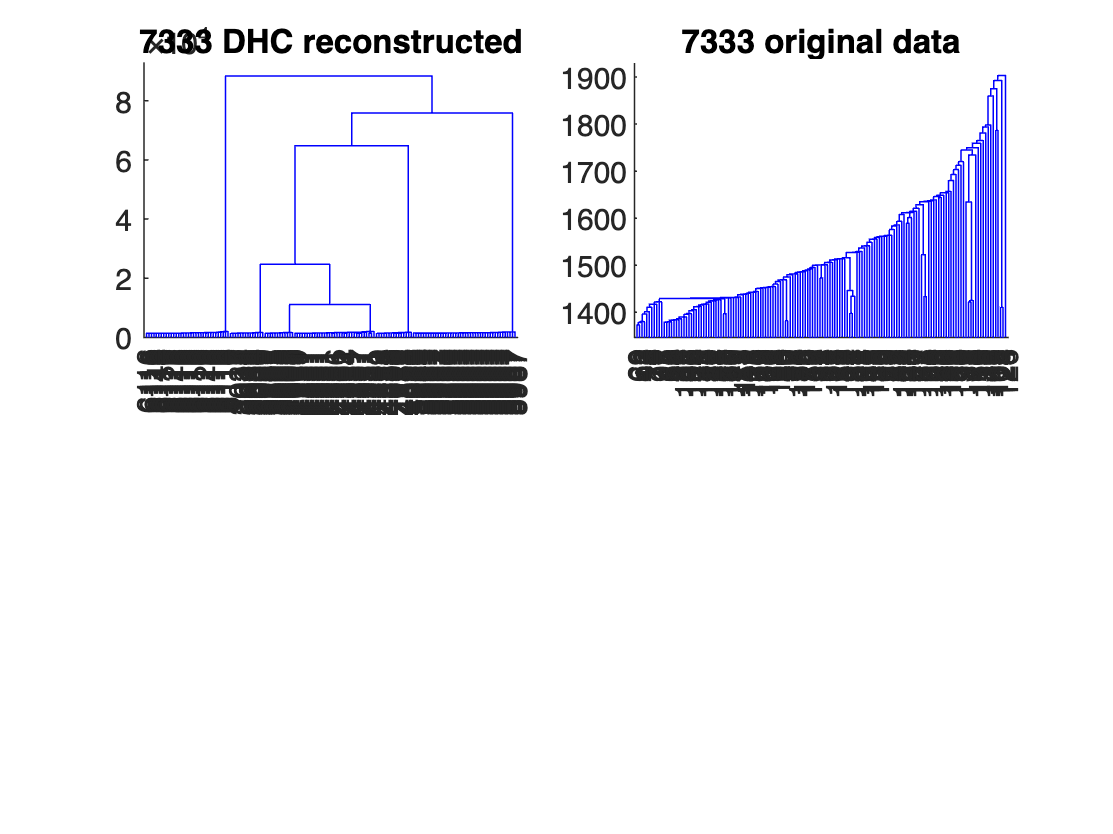



X_cell = {};
leaf_cell = [];
c2_labels = [];
c3_labels = [];
k = 0;
X_total = [];
m = 3;
cycle3_distribution = cycle3_assignment{m};
cycle3_distribution(find(cycle3_distribution(:,2)<20),:) = [];
for n = 1:length(cycle3_distribution(:,1));
    k = k+1;
    data_idx = find(sub_divide_assign == cycle3_distribution(n,1));
    X1 = X(:,data_idx)';
    X_total = [X_total;X1];
    Z = linkage(X1);
    max_leaf = max(max(Z(:,1:2)));
    X_cell{k} = X1;
    leaf_cell = [leaf_cell;max_leaf];
    num = length(data_idx);
    c2_label = subdivi_winner_idx(m);
    c3_label = cycle3_distribution(n,1);
    c2_labels = [c2_labels;c2_label*ones(num,1)];
    c3_labels = [c3_labels;c3_label*ones(num,1)];
end
X_sub3 = X_cell{1};
for i = 2:size(X_cell,2);
    X_sub3 = [X_sub3;X_cell{i} + 10*sum(leaf_cell(1:i-1))];
end
Z = linkage(X_sub3);
Z1 = linkage(X_total);
c3_labels = num2str(c3_labels);
figure;
subplot(2,2,1)
h = dendrogram(Z,150,'Labels',c3_labels);
title(string(subdivi_winner_idx(m))+' DHC reconstructed')
subplot(2,2,2)
h = dendrogram(Z1,150);
title(string(subdivi_winner_idx(m))+' original data')

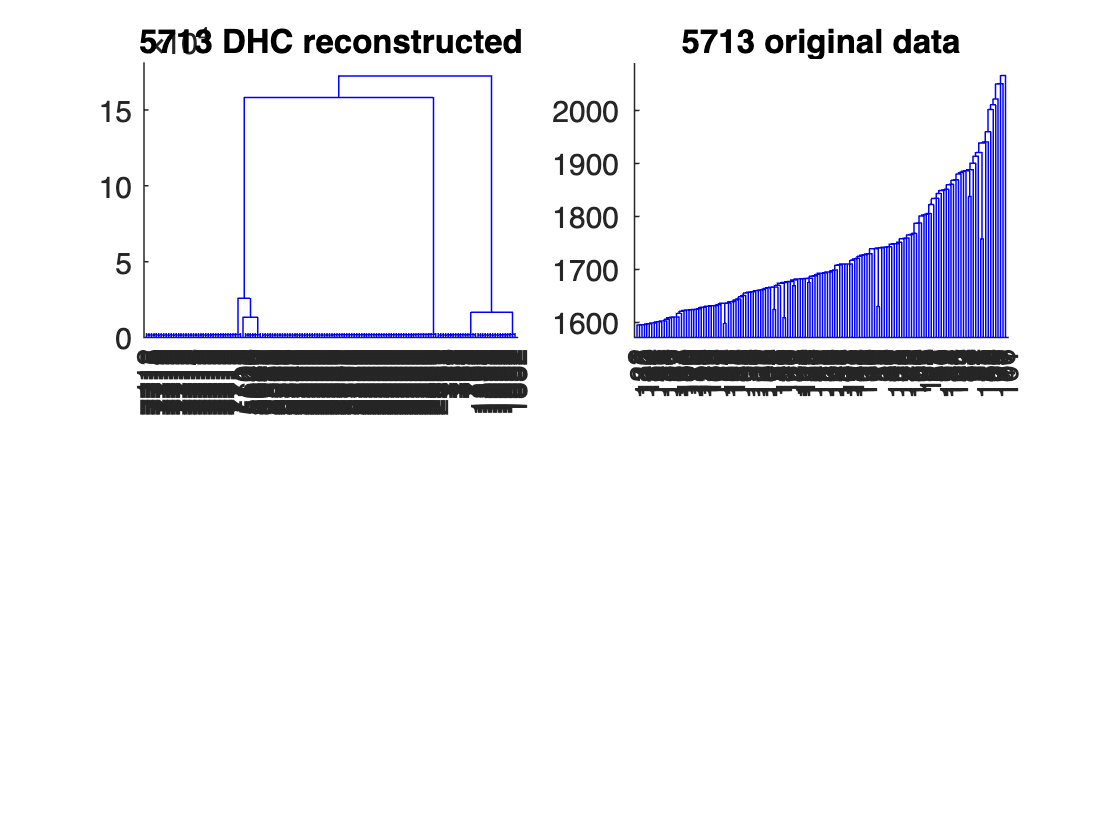




X_cell = {};
leaf_cell = [];
c2_labels = [];
c3_labels = [];
k = 0;
X_total = [];
m = 4;
cycle3_distribution = cycle3_assignment{m};
cycle3_distribution(find(cycle3_distribution(:,2)<20),:) = [];
for n = 1:length(cycle3_distribution(:,1));
    k = k+1;
    data_idx = find(sub_divide_assign == cycle3_distribution(n,1));
    X1 = X(:,data_idx)';
    X_total = [X_total;X1];
    Z = linkage(X1);
    max_leaf = max(max(Z(:,1:2)));
    X_cell{k} = X1;
    leaf_cell = [leaf_cell;max_leaf];
    num = length(data_idx);
    c2_label = subdivi_winner_idx(m);
    c3_label = cycle3_distribution(n,1);
    c2_labels = [c2_labels;c2_label*ones(num,1)];
    c3_labels = [c3_labels;c3_label*ones(num,1)];
end
X_sub4 = X_cell{1};
for i = 2:size(X_cell,2);
    X_sub4 = [X_sub4;X_cell{i} + 10*sum(leaf_cell(1:i-1))];
end
Z = linkage(X_sub4);
Z1 = linkage(X_total);
c3_labels = num2str(c3_labels);
figure;
subplot(2,2,1)
h = dendrogram(Z,150,'Labels',c3_labels);
title(string(subdivi_winner_idx(m))+' DHC reconstructed')
subplot(2,2,2)
h = dendrogram(Z1,150);
title(string(subdivi_winner_idx(m))+' original data')


% X_cell = {};
% leaf_cell = [];
% c2_labels = [];
% c3_labels = [];
% k = 0;
% X_total = [];
% m = 5;
% cycle3_distribution = cycle3_assignment{m};
% cycle3_distribution(find(cycle3_distribution(:,2)<20),:) = [];
% for n = 1:length(cycle3_distribution(:,1));
%     k = k+1;
%     data_idx = find(sub_divide_assign == cycle3_distribution(n,1));
%     X1 = X(:,data_idx)';
%     Z = linkage(X1);
%     max_leaf = max(max(Z(:,1:2)));
%     X_cell{k} = X1;
%     leaf_cell = [leaf_cell;max_leaf];
%     num = length(data_idx);
%     c2_label = subdivi_winner_idx(m);
%     c3_label = cycle3_distribution(n,1);
%     c2_labels = [c2_labels;c2_label*ones(num,1)];
%     c3_labels = [c3_labels;c3_label*ones(num,1)];
% end
% X_sub5 = X_cell{1};
% for i = 2:size(X_cell,2);
%     X_sub5 = [X_sub5;X_cell{i} + sum(leaf_cell(1:i-1))];
% end
% Z = linkage(X_sub5);
% h = dendrogram(Z,150);
% title(string(subdivi_winner_idx(m)))
% 
% X_cell = {};
% leaf_cell = [];
% c2_labels = [];
% c3_labels = [];
% k = 0;
% X_total = [];
% m = 6;
% cycle3_distribution = cycle3_assignment{m};
% cycle3_distribution(find(cycle3_distribution(:,2)<20),:) = [];
% for n = 1:length(cycle3_distribution(:,1));
%     k = k+1;
%     data_idx = find(sub_divide_assign == cycle3_distribution(n,1));
%     X1 = X(:,data_idx)';
%     Z = linkage(X1);
%     max_leaf = max(max(Z(:,1:2)));
%     X_cell{k} = X1;
%     leaf_cell = [leaf_cell;max_leaf];
%     num = length(data_idx);
%     c2_label = subdivi_winner_idx(m);
%     c3_label = cycle3_distribution(n,1);
%     c2_labels = [c2_labels;c2_label*ones(num,1)];
%     c3_labels = [c3_labels;c3_label*ones(num,1)];
% end
% X_sub6 = X_cell{1};
% for i = 2:size(X_cell,2);
%     X_sub6 = [X_sub6;X_cell{i} + sum(leaf_cell(1:i-1))];
% end
% Z = linkage(X_sub6);
% h = dendrogram(Z,150);
% title(string(subdivi_winner_idx(m)))

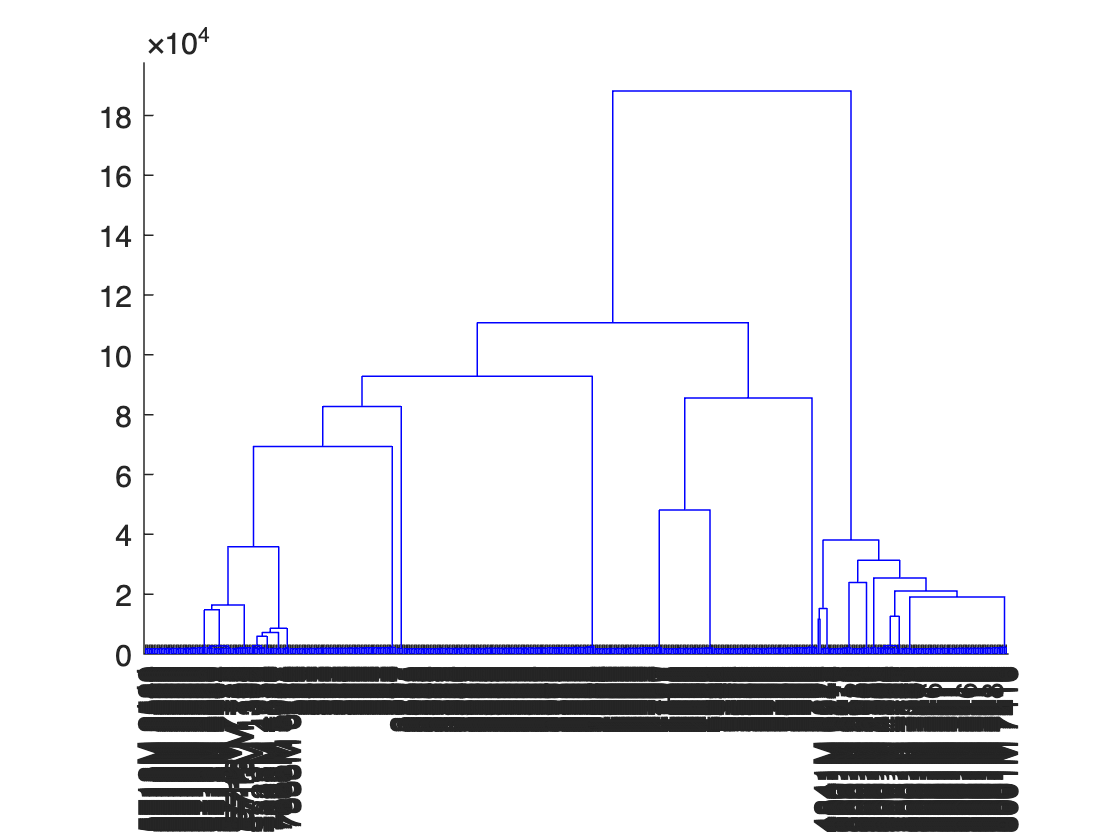


% 
% 
% for m = 1%:size(cycle3_assignment,2);
%     cycle3_distribution = cycle3_assignment{m};
%     cycle3_distribution(find(cycle3_distribution(:,2)<20),:) = [];
%     for n = 1:length(cycle3_distribution(:,1));
%         k = k+1;
%         data_idx = find(sub_divide_assign == cycle3_distribution(n,1));
%         X1 = X(:,data_idx)';
%         Z = linkage(X1);
%         max_leaf = max(max(Z(:,1:2)));
%         X_cell{k} = X1;
%         leaf_cell = [leaf_cell;max_leaf];
%         num = length(data_idx);
%         c2_label = subdivi_winner_idx(m);
%         c3_label = cycle3_distribution(n,1);
%         c2_labels = [c2_labels;c2_label*ones(num,1)];
%         c3_labels = [c3_labels;c3_label*ones(num,1)];
%     end
% end
%    
% X_total = X_cell{1};
% for i = 2:size(X_cell,2);
%     X_total = [X_total;X_cell{i} + sum(leaf_cell(1:i-1))];
% end
% 
% X_total = [X_sub;X_sub2+2000;X_sub3+6000;X_sub4+8000;X_sub5+12000;X_sub6+16000;X_sub6(end-100:end,:)+20000];
X_cluster = {};
leaf_cluster = [];
c2_labels = [];
c3_labels = [];
for m = 1:4;
    X_cell = {};
    leaf_cell = [];
    k = 0;
    cycle3_distribution = cycle3_assignment{m};
    cycle3_distribution(find(cycle3_distribution(:,2)<20),:) = [];
    for n = 1:length(cycle3_distribution(:,1));
        k = k+1;
        data_idx = find(sub_divide_assign == cycle3_distribution(n,1));
        X1 = X(:,data_idx)';
        Z = linkage(X1);
        max_leaf = max(max(Z(:,1:2)));
        X_cell{k} = X1;
        leaf_cell = [leaf_cell;max_leaf];
        num = length(data_idx);
        c2_label = subdivi_winner_idx(m);
        c3_label = cycle3_distribution(n,1);
        c2_labels = [c2_labels;c2_label*ones(num,1)];
        c3_labels = [c3_labels;c3_label*ones(num,1)];
    end
    X_sub = X_cell{1};
    for i = 2:size(X_cell,2);
        X_sub = [X_sub;X_cell{i} + sum(leaf_cell(1:i-1))];
    end
    X_cluster{m} = X_sub;
    Z = linkage(X_sub);
    leaf_cluster = [leaf_cluster;max(max(Z(:,1:2)))];
end

X_total = X_cluster{1};
for i = 2:size(X_cluster,2);
    X_total = [X_total;X_cluster{i} + 2*sum(leaf_cluster(1:i-1))];
end

non_divi_labels  = [];
non_divi_leaf = [];
for i = 1:length(non_divi);
    this = non_divi(i);
    data_idx = find(clustAssignments == this);
    num = length(data_idx);
    X1 = X(:,data_idx)';
    Z = linkage(X1);
    X_total = [X_total;X1 + 2*sum(non_divi_leaf)+2*sum(leaf_cluster)];
    non_divi_leaf = [non_divi_leaf;max(max(Z(:,1:2)))];
    non_divi_labels = [non_divi_labels;this*ones(num,1)];
end

Z_LIHC = linkage(X_total);
c2_labels = num2str(c2_labels);
c3_labels = num2str(c3_labels,' M %d');
non_divi_labels = num2str(non_divi_labels);

figure;
comb_labels = strvcat(strcat(c2_labels,c3_labels),non_divi_labels);
%labels = cellstr(strcat(c2_labels,c3_labels));
%h = dendrogram(Z,500);
h = dendrogram(Z_LIHC,500,'Labels',comb_labels);